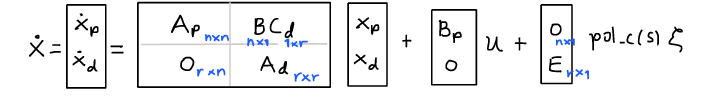

# ADRC (Adaptive Disturbance Rejection in Controller) GPI And OBS

#### Controller OBS

syms s
format long
n=1

n =      1


r=1

r =      1


m=n+r

m =      2


k=0.05

k =    0.050000000000000


Tau =20*60

Tau =         1200


b0 = k/Tau

b0 =      4.166666666666667e-05


A=zeros(m,m);
for i=1:m-1
    A(i,i+1)=1;
end
A

A =      0     1
     0     0


Cau=zeros(1,m);
Cau(1,1)=1;


**Planta orden 1:**

A_p=A(1:n,1:n)

A_p =      0


B_p(n,1)=1

B_p =      1


C_p=Cau(1,1:n)

C_p =      1


**Un estado extendido:**

A_d=[0]

A_d =      0


B_d=[1]

B_d =      1


C_d=[1]

C_d =      1


OBS

Aau=[A_p,B_p*C_d;zeros(r,n),A_d]

Aau =      0     1
     0     0


Bau=[B_p;zeros(r,1)]

Bau =      1
     0


Cau=zeros(1,m)

Cau =      0     0


Cau(1,1)=1

Cau =      1     0




Dau=[0]

Dau =      0




%K = [0.000941,1]
K = [0.003,1]

K =    0.003000000000000   1.000000000000000


polos=-0.03;
P=ones(1,m)*polos

P =   -0.030000000000000  -0.030000000000000


%p=[-0.02 -0.03]
p=[-0.015 -0.016]

p =   -0.015000000000000  -0.016000000000000


%ganancias del observador
L=acker(Aau',Cau',P)'

L =    0.060000000000000
   0.000900000000000


A_o=Aau-L*Cau

A_o =   -0.060000000000000   1.000000000000000
  -0.000900000000000                   0


eig(A_o)

ans =  -0.030000000000000 + 0.000000000322754i
 -0.030000000000000 - 0.000000000322754i


poly([-1,-1])

ans =      1     2     1



%raices polinomio caracteristico, error de seguimiento
pol_seg=-10;
poly(pol_seg*ones(1,n))

ans =      1    10


**Controller GPI**

%% Desired controller

 %kiq = poly([-0.0014 -0.0012 -0.001])
 kiq = poly([-0.0014 -0.0012])

kiq =    1.000000000000000   0.002600000000000   0.000001680000000


 
 % P  = [62.4 0.04032]
 % L_E= -0.002842
 % E1 = [1 0.002842]
 % ESO-> GPI
 %numGpi = ([0.0001273 (-0.0000000000002185+0.03878) 0.00003383])/0.0025
 %denGpi = [1 0.0001273/0.0025  -0.0000000000002185/0.0025]
 %numGpi = [0.012695 0.000011076]*0.0509 
 %denGpi = [1 0.0509  0]
 % GPI from ESO
 k2=K(1)+L(1)

k2 =    0.063000000000000


 k1=K(1)*L(1)+L(2)

k1 =    0.001080000000000


 k0=K(1)*L(2)

k0 =      2.700000000000000e-06


 numGpi = [k1 k0] 

numGpi =    0.001080000000000   0.000002700000000


 denGpi = [1 k2 0]

denGpi =    1.000000000000000   0.063000000000000                   0


 % ESO Completo
 numC = [0.03878 0.00003383]

numC =    0.038780000000000   0.000033830000000


 denC = [0.0025 0.0001273 -0.0000000000002185]

denC =    0.002500000000000   0.000127300000000  -0.000000000000219


 % ESO in FT with anti-windup

 % with GPI
 % P_  = [15.51 0.01353]
 % L_E= [0.00004203 -0.0006442]
 % E1 = [1 0.05087 0.0006442]

 % with ESO FT
 % P_  = [22.96 0.02033]
 % L_E= [0.0000552 -0.0009531]
 % E1 = [1 0.06089 0.0009531]


 %with GPI with K
 P_  = [k1 k0]

P_ =    0.001080000000000   0.000002700000000


 L_E= [-k1]

L_E =   -0.001080000000000


 E1 = [1 k2 k1]

E1 =    1.000000000000000   0.063000000000000   0.001080000000000




% Expande la expresión

% Initial and final time
t0 = 0;
tf = 1800;

% Initial and final values of the reference
y_ref_0 = 0;        % OD inicial [mg/L]
y_ref_f = 2;        % consigna [mg/L]

dy_ref_0  = 0;
dy_ref_f  = 0;

d2y_ref_0 = 0;
d2y_ref_f = 0;

% Matrix of the system of equations
A_y=[ 1*t0^5   1*t0^4   1*t0^3   1*t0^2   t0  1;
      5*t0^4   4*t0^3   3*t0^2   2*t0^1   1   0;
     20*t0^3  12*t0^2   6*t0^1   2        0   0;
      1*tf^5   1*tf^4   1*tf^3   1*tf^2   tf  1;
      5*tf^4   4*tf^3   3*tf^2   2*tf^1   1   0;
     20*tf^3  12*tf^2   6*tf^1   2        0   0];

% Vector of initial and final values of the reference
y_t0_tf=[y_ref_0;dy_ref_0;d2y_ref_0;...
         y_ref_f;dy_ref_f;d2y_ref_f];

% Coefficients of the polynomial reference
Pa=A_y\y_t0_tf;


a5=Pa(1)

a5 =      6.350657928161374e-16


a4=Pa(2)

a4 =     -2.857796067672617e-12


a3=Pa(3)

a3 =      3.429355281207139e-09


a2=Pa(4)

a2 =      0


a1=Pa(5)

a1 =      0


a0=Pa(6)

a0 =      0
